Load equations and symbols from file

load symbols.mat
load CoreEquations.mat
load DesignParameters.mat
%load DesignParametersExtraMass.mat
% load DesignParametersExtraTail.mat

Calculate torque requirements for different movements

%Stage 1: Lifting against step from ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    % T_z == 12;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

[sol1, unsolved] = mysolver(Eqns)
sol1.T_z/2
%Draw positions
drawfigure(sol1);


% sol = sol1
% f=figure('visible','on');
% hold on;
% %wheels
% circle(sol.s61, sol.s62, sol.rw);
% line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
% 
% circle(sol.s51, sol.s52, sol.rw);
% line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
% 
% %frame
% line([sol.s51,sol.s61],[sol.s52,sol.s62])
% 
% %Tail
% line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
% figure
% axis equal;
% axis on;
% ax = gca;
% ax.XAxisLocation = 'origin';
% ax.YAxisLocation = 'origin';
% xlim([-0.7,0.7])
% %ylim([-0.1, 0.5])
% %step
% corner(:,1) = [sol.step_start1-10; sol.step_start2];
% for i= 1:5
%     corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
%     corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
% end
% line(corner(1,:), corner(2,:))
% hold off;

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    s62 == rw; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

[sol2, unsolved] = mysolver(Eqns, 1);
sol2.T_z/2
drawfigure(sol2);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z/2
drawfigure(sol3);

%Stage 1: Lifting against step from first step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    pi/2 < t73; t73 < pi;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z/2
drawfigure(sol3);

%Stage 6: Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    s62 == rw+step_height; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol4 = mysolver(Eqns);
sol4.T_z/2
drawfigure(sol4);

%Stage 6:Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol5 = mysolver(Eqns);
sol5.T_z/2
drawfigure(sol5);

%Stage 4:Lifting against step from second step with tail on first step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
sol6 = mysolver(Eqns);
sol6.T_z/2
drawfigure(sol6);

Test stall torques across movements each movement


%Test stall torques across stage 1 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions1 = solveParallel(Eqns, t13, linspace(0, pi/2, 100))

for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    Crange(i) = solutions1(i).C_friction5;
    thetarange(i) =solutions1(i).t13*180/pi;
end

plot(thetarange, Trange)
hold on
plot(thetarange, Crange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off

%Test stall torques across stage 2 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4);
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set vertical accelleration of top wheel to zero to solve for movement
    a62 == 0;
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions2 = solveParallel(Eqns, t13, linspace(pi/2, pi-0.74188086214972967258453186960347, 100))

for i = 1:length(solutions2)
    Trange(i) = solutions2(i).T_z;
    Crange = solutions2(i).C_friction5;
    thetarange(i) =solutions2(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([90,180-42.5])
ylim([-1.2, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 3 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions3 = solveParallel(Eqns, t13, linspace(-0.74188086214972967258453186960347, 0, 100));

for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    thetarange(i) =solutions3(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

%Test stall torques across stage 1 movement on second step
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw + step_width; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions12 = solveParallel(Eqns, t13, linspace(0, pi/2, 100))

for i = 1:length(solutions12)
    Trange(i) = solutions12(i).T_z;
    thetarange(i) =solutions12(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 2 movement on second step
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4);
    %Set position of front wheel
    s51 == -rw + step_width; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions22 = solveParallel(Eqns, t13, linspace(pi/2, pi-0.74188086214972967258453186960347, 100))

for i = 1:length(solutions22)
    Trange(i) = solutions22(i).T_z;
    thetarange(i) =solutions22(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 3 movement on second step
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width*2-rw-0.075; s52 == rw+step_height*2;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions32 = solveParallel(Eqns, t13, linspace(-0.74188086214972967258453186960347, 0, 100));

for i = 1:length(solutions32)
    Trange(i) = solutions32(i).T_z;
    thetarange(i) =solutions32(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

%Test stall torques across stage 4 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions4 = solveParallel(Eqns, t13, linspace(0, pi/2, 100));

for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    thetarange(i) =solutions4(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")


%Test stall torques across stage 5 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4);
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions5 = solveParallel(Eqns, t13, linspace(pi/2, pi-0.74188086214972967258453186960347, 100))

for i = 1:length(solutions5)
    Trange(i) = solutions5(i).T_z;
    thetarange(i) =solutions5(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 6 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 3*step_width-rw-0.075; s52 == rw+3*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions6 = solveParallel(Eqns, t13, linspace(-0.74188086214972967258453186960347, 0, 100));

for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    thetarange(i) =solutions6(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

% save solutions.mat solutions1 solutions2 solutions3 solutions12 solutions22 solutions32 solutions4 solutions5 solutions6
% load solutions.mat

Plot torques across complete movement

%First movement 1
for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    Crange(i) = solutions1(i).C_friction5;
    thetarange(i) =solutions1(i).t13*180/pi;
end
PlotTorque = Trange;
PlotFriction = Crange;
PlotTheta = thetarange;

%Movement 2
for i = 1:length(solutions2)
    Trange(i) = solutions2(i).T_z;
    Crange(i) = solutions2(i).C_friction5;
    thetarange(i) =solutions2(i).t13*180/pi;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 3
for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    Crange(i) = solutions3(i).C_friction5;
    thetarange(i) =solutions3(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 1 on step
for i = 1:length(solutions12)
    Trange(i) = solutions12(i).T_z;
    Crange(i) = solutions12(i).C_friction5;
    thetarange(i) =solutions12(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 2 on step
for i = 1:length(solutions22)
    Trange(i) = solutions22(i).T_z;
    Crange(i) = solutions22(i).C_friction5;
    thetarange(i) =solutions22(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 3 on step
for i = 1:length(solutions32)
    Trange(i) = solutions32(i).T_z;
    Crange(i) = solutions32(i).C_friction5;
    thetarange(i) =solutions32(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 4
for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    Crange(i) = solutions4(i).C_friction5;
    thetarange(i) =solutions4(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 5
for i = 1:length(solutions5)
    Trange(i) = solutions5(i).T_z;
    Crange(i) = solutions5(i).C_friction5;
    thetarange(i) =solutions5(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 6
for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    Crange(i) = solutions6(i).C_friction5;
    thetarange(i) =solutions6(i).t13*180/pi+540;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 4
for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    Crange(i) = solutions4(i).C_friction5;
    thetarange(i) =solutions4(i).t13*180/pi+540;
end
PlotTorque = [PlotTorque, Trange, 0];
PlotFriction = [PlotFriction, Crange, 0];
PlotTheta = [PlotTheta, thetarange, 630];

for i= 1:length(PlotTheta)
    if PlotFriction(i) < 0
        PlotFriction(i) = 0;
    end
    if PlotTorque(i) < 0
        PlotTorque(i) = 0;
    end
end
% save bigplots.mat PlotTorque PlotFriction PlotTheta

% load bigplots.mat
f= figure;
plot(PlotTheta, PlotTorque)
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
f.CurrentAxes.XTick=0:90:630;
xlim([0,630])
xline(90:90:630,"--")
xline([180:180:540]-0.74188086214972967258453186960347*180/pi,"--")
hold off

f= figure;
plot(PlotTheta, PlotFriction)
ylabel("Coefficient of friction required to prevent slipping")
xlabel("LIM Angle [°]")
f.CurrentAxes.XTick=0:90:630;
xlim([0,630])
xline(90:90:630,"--")
xline([180:180:540]-0.74188086214972967258453186960347*180/pi,"--")
hold off

drawfigure(solutions1(1))

testvar = vpa(PlotTheta)

%Test stall torques with varying gear ratios
%remove certain parameters
reducedParameters = setdiff(DesignParameters, assignment_gears)
%add back certain parameters, and add relation for gear separations to be
%based on gear ratios
new_assignment_gears = [%r3 == 0.027612244897959183673469387755102;
    l5_ab == 0.041+0.07;
    rw == 0.075; l7_ab == 0.425; 
    N_idler == 33; N_sun == 50; C_friction7 == 0.2;];

reducedEquations = setdiff(Core_equations, eqns_radius)

new_eqns_radius = [r2==separation23*N_sun/(N_sun+N_idler)
    r3==separation35*N_idler/(N_planet+N_idler)
    r3==separation23*N_idler/(N_idler+N_sun)
    r4==r3
    r5==separation35*N_planet/(N_planet+N_idler)
    r6==r5];

Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    reducedEquations; new_eqns_radius; reducedParameters; new_assignment_gears
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)
solutionset = [];
for j = 1:24
    Trange = [];
    Crange = [];
    theta=linspace(0.4, 0.8, 40);
    %solve for gear radii
    tempsol = mysolver([new_eqns_radius; ...
    separation23 == l3_ab;
    separation35==l5_ab-l3_ab; ...
    l5_ab == 0.041+0.07;
    N_idler == 33; N_sun == 50; ...
    N_planet == j], 1, sol)
    % [sol2, unsolved2]= mysolver([unsolved; N_planet == j;], 0, sol);
    solutionsGR=mysolver([unsolved; t13 == theta(1)], 1, tempsol)
    solutionsGR(length(theta)) = solutionsGR(1);
    parfor i = 1:length(theta)
        solutionsGR(i) = mysolver([unsolved; t13 == theta(i)], 2, tempsol);
        try
            Trange(i) = solutionsGR(i).T_z;
            Crange(i) = solutionsGR(i).C_friction5;
            Frange(i) = solutionsGR(i).gfa5;
        catch
            Trange(i) = 0;
            Crange(i) = 0;
            Frange(i) = 0;
        end
    end
    j
    [Tmax(j),idxT] = max(Trange);
    [Cmax(j),idxC] = max(Crange);
    [Fmax(j),idxF] = max(Frange);
    Tmax
    Cmax
    idxT
    idxC
    idxF
end


[solvy, unsolved] = mysolver([new_eqns_radius; ...
    separation23 == l3_ab;
    separation35==l5_ab-l3_ab; ...
    l5_ab == 0.041+0.07;
    N_idler == 33; N_sun == 50; ...
    N_planet == 25])

% save GRplots.mat Tmax Cmax Fmax
load GRplots.mat

plot(50./(1:24), Tmax(1:24))
ylabel("Torque required [Nm]")
xlabel("Gear ratio [N_{Sun} / N_{Planet}]")
hold off

plot(50./(1:24), Cmax(1:24))
ylabel("Coefficient of friction required to prevent slipping")
xlabel("Gear ratio [N_{Sun} / N_{Planet}]")
hold off

plot(50./(1:24), Fmax(1:24))
ylabel("Force on planet gear tooth")
xlabel("Gear ratio [N_{Sun} / N_{Planet}]")
hold off

tempsol = mysolver([new_eqns_radius; ...
    separation23 == l3_ab;
    separation35==l5_ab-l3_ab; ...
    l5_ab == 0.041+0.07;
    N_idler == 33; N_sun == 50; ...
    N_planet == 8], 1, sol)
tempsol.r2+tempsol.r5

Create an animation by using the Runge Kutta method for discrete ODE solution

%Motor torque is not constant, create function to determine motor torque
%based on speed and voltage
motor_stallTorque = 6; % Nm
motor_NLSpeed = 0.6; %rad/s
syms speed stallTorque voltage 
eqns_motor = [
    speed == tv23;
    T_z == 2*motor_stallTorque*(voltage/12.0-speed/motor_NLSpeed)
    stallTorque == motor_stallTorque*(voltage/12.0)]


%Incomplete solution for movement1
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked_simple; condition_wheel2NoContact; eqns_motor; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];
Stage1Sols = timedomainSolver(Eqns, [t13 == 0; t23 ==0; tv13 == 0; tv23 == 0;], 't13', 'greaterThan', pi/2, 2)
% save stage1sols.mat Stage1Sols

% load stage1sols.mat
%Incomplete solution for movement2
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4); eqns_motor;
    %Set position of front wheel
    s52 == rw; s51_offset == -rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];
Stage2Sols = timedomainSolver(Eqns, [t13 == Stage1Sols(end).t13; t23 == Stage1Sols(end).t23; tv13 == Stage1Sols(end).tv13; tv23 == Stage1Sols(end).tv23;s51 == -rw; t53 == Stage1Sols(end).t53; s51 == -rw; s52 == rw;], 's62', 'lessThan', Stage1Sols(end).step_height+Stage1Sols(end).rw, 2)
% save stage2sols.mat Stage2Sols

% load stage2sols.mat
%Incomplete solution for movement3
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants   ; eqns_motor;
    %Set position of front wheel
    s52 == rw+step_height;
    %Set Motor voltage 
    stallTorque == 6;
    ];
% interrimsol = mysolver([Eqns; t63 == Stage2Sols(end).t53; s61 == Stage2Sols(end).s51; s62 == Stage2Sols(end).s52; tv13 == 0; tv23 == 0;])
% drawfigure(interrimsol)
%Calculate speeds
distancetoroll = interrimsol.step_width -interrimsol.rw- interrimsol.s51
endangle=-10*pi/180
t23speed = 0.56
t13init = interrimsol.t13
t13delta = endangle-t13init
t53init = interrimsol.t53
t53end = t53init + distancetoroll/interrimsol.rw
t53delta = t53end-t53init

% interrimsol2 = mysolver([Eqns; t63 == Stage2Sols(end).t53; s61 == Stage2Sols(end).s51; s62 == Stage2Sols(end).s52; tv23 == t23speed; tv53/tv13 == t53delta/t13delta; time == 0])
spd5=interrimsol2.tv53
spd1=interrimsol2.tv13
time1=double(t13delta/spd1)

framePeriod = 0.0256;
nframes = double(floor(time1/framePeriod))+1;
endtime=(nframes-1)*framePeriod;
frameTimes = 0:framePeriod:endtime;
Stage3Sols(nframes) = interrimsol2;

for i = 1:nframes
    Stage3Sols(i) = mysolver([Eqns; tv13 == spd1; tv53 == spd5; t13==t13init + spd1*time; t53==t53init + spd5*time; s51_offset == interrimsol2.s51_offset; time == frameTimes(i)]);
    i
end



% Stage3Sols = timedomainSolver([Eqns; s51_offset == interrimsol.s51_offset], [s61 == Stage2Sols(end).s51; s62 == Stage2Sols(end).s52; tv13 == 0; tv23 == 0;], 's51', 'greaterThan', Stage1Sols(end).step_width-Stage1Sols(end).rw, 1)
% save stage3sols.mat Stage3Sols

%Incomplete solution for movement1-2
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked_simple_continuous; condition_wheel2NoContact; eqns_motor; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw+step_width; s52 == rw + step_height; s51_offset == Stage3Sols(end).s51_offset
    %Set Motor voltage 
    stallTorque == 6;
    ];
Stage12Sols = timedomainSolver(Eqns, [t13 == Stage3Sols(end).t13; t53 ==Stage3Sols(end).t53; tv13 == Stage3Sols(end).tv13; tv23 == Stage3Sols(end).tv23;], 't13', 'greaterThan', pi/2, 2)
% save stage12sols.mat Stage1Sols

% load stage1sols.mat
%Incomplete solution for movement2-2
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4); eqns_motor;
    %Set position of front wheel
    s52 == Stage12Sols(end).s52;  s51_offset == Stage3Sols(end).s51_offset;
    %Set Motor voltage 
    stallTorque == 6;
    ];
Stage22Sols = timedomainSolver(Eqns, [t13 == Stage12Sols(end).t13; t53 == Stage12Sols(end).t53; tv13 == Stage12Sols(end).tv13; tv23 == Stage12Sols(end).tv23;s51 == step_width - rw; t53 == Stage12Sols(end).t53; s52 == rw;], 's62', 'lessThan', Stage12Sols(end).step_height*2+Stage12Sols(end).rw, 2)
% save stage22sols.mat Stage2Sols

% load stage2sols.mat
%Incomplete solution for movement3
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants   ; eqns_motor;
    %Set position of front wheel
    s52 == rw+step_height*2;
    %Set Motor voltage 
    stallTorque == 6;
    ];
interrimsol = mysolver([Eqns; t63 == Stage22Sols(end).t53; s61 == Stage22Sols(end).s51; s62 == Stage22Sols(end).s52; tv13 == 0; tv23 == 0;])

interrimsol = struct with fields:
      C_friction5: 0.53868796954170453155947819173363
      C_friction7: 0.2
        F_react51: 45.032874795419454103991873865615
        F_react52: 83.597327844042499461521682387518
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react71: -7.5049679576793301510625240111625
        F_react72: 37.524839788396650755312620055812
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
    L_body_centre: 0.0437
        M_react53: -3.3774656096564590577993905399211
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_

% drawfigure(interrimsol)
%Calculate speeds
distancetoroll = interrimsol.step_width*2 -interrimsol.rw- interrimsol.s51

$$distancetoroll = 0.12252303911548021014853257837803$$

endangle=-10*pi/180

endangle = -0.1745

t23speed = 0.56

t23speed = 0.5600

t13init = interrimsol.t13

$$t13init = -0.74188086214972967258453186960347$$

t13delta = endangle-t13init

$$t13delta = 0.74188086214972967258453186960347-\frac{\pi }{18}$$

t53init = interrimsol.t53

$$t53init = -0.6645253312418766876631855949912$$

t53end = t53init + distancetoroll/interrimsol.rw

$$t53end = 0.96911519029785944765058211671586$$

t53delta = t53end-t53init

$$t53delta = 1.6336405215397361353137677117071$$


interrimsol2 = mysolver([Eqns; t63 == Stage22Sols(end).t53; s61 == Stage22Sols(end).s51; s62 == Stage22Sols(end).s52; tv23 == t23speed; tv53/tv13 == t53delta/t13delta; time == 0])

interrimsol2 = struct with fields:
      C_friction5: 0.37070269980988523379097674191103
      C_friction7: 0.2
        F_react51: 3.2140297232394262097840353196345
        F_react52: 8.6701006625733785328724900727494
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react71: -0.80426430124308830877333064668641
        F_react72: 4.021321506215441543866653233432
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
    L_body_centre: 0.0437
        M_react53: -0.24105222924295696573380264897259
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          

spd5=interrimsol2.tv53

$$spd5 = 1.0098943673500631495201374589578$$

spd1=interrimsol2.tv13

$$spd1 = 0.35072678370744422679601848438872$$

time1=double(t13delta/spd1)

time1 = 1.6176


framePeriod = 0.0256;
nframes = double(floor(time1/framePeriod))+1;
endtime=(nframes-1)*framePeriod;
frameTimes = 0:framePeriod:endtime;
Stage32Sols(nframes) = interrimsol2;

for i = 1:nframes
    Stage32Sols(i) = mysolver([Eqns; tv13 == spd1; tv53 == spd5; t13==t13init + spd1*time; t53==t53init + spd5*time; s51_offset == interrimsol2.s51_offset; time == frameTimes(i)]);
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64




% Stage3Sols = timedomainSolver([Eqns; s51_offset == interrimsol.s51_offset], [s61 == Stage2Sols(end).s51; s62 == Stage2Sols(end).s52; tv13 == 0; tv23 == 0;], 's51', 'greaterThan', Stage1Sols(end).step_width-Stage1Sols(end).rw, 1)
% save stage3sols.mat Stage3Sols


framePeriod = 0.0256;
testsols1 = syncSolutions(Stage1Sols, framePeriod);
testsols2 = syncSolutions(Stage2Sols, framePeriod);
testsols3 = Stage3Sols;

testsols3 = 1×65 struct array with fields:
    C_friction5
    C_friction7
    F_react51
    F_react52
    F_react53
    F_react61
    F_react62
    F_react63
    F_react71
    F_react72
    F_react73
    I1
    I2
    I3
    I4
    I5
    I6
    I7
    L_body_centre
    M_react53
    M_react61
    M_react62
    M_react63
    N_idler
    N_planet
    N_sun
    T_z
    a11
    a12
    a13
    a21
    a22
    a23
    a31
    a32
    a33
    a41
    a42
    a43
    a51
    a52
    a53
    a61
    a62
    a63
    a71
    a72
    a73
    f21
    f22
    f23
    f31
    f32
    f33
    f41
    f42
    f43
    f51
    f52
    f53
    f61
    f62
    f63
    f71
    f72
    f73
    g2
    gf11
    gf12
    gf13
    gf21
    gf22
    gf23
    gf31
    gf32
    gf33
    gf41
    gf42
    gf43
    gf51
    gf52
    gf53
    gf61
    gf62
    gf63
    gf71
    gf72
    gf73
    gfa3
    gfa4
    gfa5
    gfa6
    l11
    l12
    l13
    l21
    l22
    l23
    l31
    l32
    l33
    l3_ab
    l41

testsols12 = syncSolutions(Stage12Sols, framePeriod);
testsols22 = syncSolutions(Stage22Sols, framePeriod);
testsols32 = Stage32Sols;

testsols32 = 1×64 struct array with fields:
    C_friction5
    C_friction7
    F_react51
    F_react52
    F_react53
    F_react61
    F_react62
    F_react63
    F_react71
    F_react72
    F_react73
    I1
    I2
    I3
    I4
    I5
    I6
    I7
    L_body_centre
    M_react53
    M_react61
    M_react62
    M_react63
    N_idler
    N_planet
    N_sun
    T_z
    a11
    a12
    a13
    a21
    a22
    a23
    a31
    a32
    a33
    a41
    a42
    a43
    a51
    a52
    a53
    a61
    a62
    a63
    a71
    a72
    a73
    f21
    f22
    f23
    f31
    f32
    f33
    f41
    f42
    f43
    f51
    f52
    f53
    f61
    f62
    f63
    f71
    f72
    f73
    g2
    gf11
    gf12
    gf13
    gf21
    gf22
    gf23
    gf31
    gf32
    gf33
    gf41
    gf42
    gf43
    gf51
    gf52
    gf53
    gf61
    gf62
    gf63
    gf71
    gf72
    gf73
    gfa3
    gfa4
    gfa5
    gfa6
    l11
    l12
    l13
    l21
    l22
    l23
    l31
    l32
    l33
    l3_ab
    l4

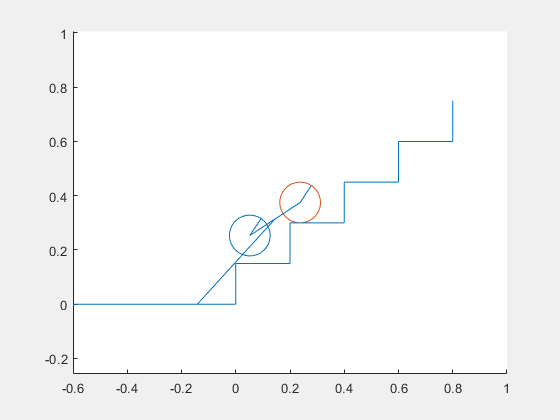

F1=makeFrames(testsols1);
F2=makeFrames(testsols2);
F3=makeFrames(testsols3);
F12=makeFrames(testsols12);
F22=makeFrames(testsols22);
F32=makeFrames(testsols32);
F=[F1,F2,F3,F12,F22,F32];

fig = figure;

movie(fig, F, 1, 1/framePeriod);

Obsolete code

[sol, unsolved] = mysolver(Eqns, 0);

Eqns=[unsolved;
    t13 == 0; t23 ==0 
    tv13 == 0; tv23 == 0;
    ]; 
[sol2, unsolved2] = mysolver(Eqns, 2, sol)

preallocationSize = 10000
syms time

%Start calculations
% frameeqs = unsolved
% Step_Value = 0.0001;
% t_beg = 0;
% t_end = 10;
% t_initial=0;
% u_initial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% % Routine starts here
% h=Step_Value;
% % t=t_beg:h:t_end;
% t= t_initial
% u=zeros(4,preallocationSize);
% u(:,1)=u_initial;

% sol2.time = 0
% %preallocate
% framesol(preallocationSize) = sol2;
% i=1
% load framedata2.mat
oscillationcounter = 10

while (u(1,i) < pi/2)&&(i<preallocationSize) 
    t0=t;
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol(i)=mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4; time == t0], 2, sol);
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol1 = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 2);
    k2 = [tempsol1.tv13; tempsol1.tv23; tempsol1.ta13; tempsol1.ta23];
    tempsol2 = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 2);
    k3 = [tempsol2.tv13; tempsol2.tv23; tempsol2.ta13; tempsol2.ta23];
    tempsol3 = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 2);
    k4 = [tempsol3.tv13; tempsol3.tv23; tempsol3.ta13; tempsol3.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    %decrease step size if oscillating in runge kutta
    ks=[k1, k2, k3, k4];
    oscillating = 0;
    for j = 1:4
        if abs(sum(sign(ks(j,:)))) ~= 4
            oscillating = 1
            break
        end
    end
    largeValues = 0;
    for j = 3:4
        if mean(abs(ks(j,:))) > 1
            largeValues = 1
            break
        end
    end
    if (oscillating)&&(largeValues)&&(h>0.0001)
        h = h/2
        oscillationcounter = 0
    else
        percentComplete = double(framesol(i-1).t13 / pi*180/90 *100)
        i=i+1
        t = t + h
        oscillationcounter = oscillationcounter + 1
        %increase step size if oscillating hasn't happened for a while
        if (oscillationcounter > 10)&&(h<= 0.01)
            h = h*2
        end
        %save results periodically
        if mod(i, 10) == 0
            save framedata2.mat framesol h t u i
        end
    end
end

positionfields = {'s51'; 's52'; 's61';'s62'; 'rw'; 't53';'t63';'s11'; 's12';'s7End1';'s7End2';'time';
    'step_start1';'step_start2';'step_height';'step_width'};
f = fieldnames(framesol);
f2=f(~ismember(f,positionfields));
Stage1Sols= rmfield(framesol,f2);
for i = 1:length(Stage1Sols)
    if isempty(Stage1Sols(i).s61)
        endIndex = i-1;
        break
    end
end
Stage1Sols = Stage1Sols(1:endIndex)
% save stage1sols.mat Stage1Sols


framePeriod = 0.0256

nframes=double(floor(framesol(end).time/framePeriod))+1
endtime=(nframes-1)*framePeriod
frameTimes = 0:framePeriod:endtime
clear framesol2 
framesol2(nframes) = framesol(1);

k = 1
for j=1:length(frameTimes)
    for i = k:length(framesol)
        if framesol(i).time >= frameTimes(j)
            framesol2(j) = framesol(i);
            k = i;
            break
        end
    end
end


F=makeFrames(framesol2)

fig = figure;



movie(fig, F, 1, 1/framePeriod);




f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_width], [sol.step_height, sol.step_height])
hold off;



function f = drawfigure(sol)
    f=figure('visible','on');
    hold on;
    %wheels
    circle(sol.s61, sol.s62, sol.rw);
    line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
    
    circle(sol.s51, sol.s52, sol.rw);
    line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
    
    %frame
    line([sol.s51,sol.s61],[sol.s52,sol.s62])
    
    %Tail
    line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [sol.step_start1-10; sol.step_start2];
    for i= 1:5
        corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
        corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
end

function h = circle(x,y,r)
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit);
end

function solutions = solveParallel(Eqns, var, range)
    [sol, unsolved] = mysolver(Eqns, 0);
    N = length(range);
    solutions=mysolver([unsolved; var == range(1)], 2, sol);
    solutions(N) = solutions(1);
    parfor i = 1:N
        solutions(i) = mysolver([unsolved; var == range(i)], 2, sol);
    end
end

function F = makeFrames(solutionSet)
    nframes = length(solutionSet);
    F(nframes) = struct('cdata',[],'colormap',[]);
    for j=1:nframes
        f=figure('visible','off');
        hold on;
        %wheels
        circle(solutionSet(j).s61, solutionSet(j).s62, solutionSet(j).rw);
        line([solutionSet(j).s61,solutionSet(j).s61+solutionSet(j).rw*cos(-solutionSet(j).t53+pi/4)],[solutionSet(j).s62,solutionSet(j).s62+solutionSet(j).rw*sin(-solutionSet(j).t53+pi/4)])
        
        circle(solutionSet(j).s51, solutionSet(j).s52, solutionSet(j).rw);
        line([solutionSet(j).s51,solutionSet(j).s51+solutionSet(j).rw*cos(-solutionSet(j).t53+pi/4)],[solutionSet(j).s52,solutionSet(j).s52+solutionSet(j).rw*sin(-solutionSet(j).t53+pi/4)])
        
        %frame
        line([solutionSet(j).s51,solutionSet(j).s61],[solutionSet(j).s52,solutionSet(j).s62])
        
        %Tail
        line([solutionSet(j).s11,solutionSet(j).s7End1],[solutionSet(j).s12,solutionSet(j).s7End2])
        
        axis equal;
        xlim([-0.6,1])
        %ylim([-0.1, 0.5])
        %step
        corner(:,1) = [solutionSet(j).step_start1-10; solutionSet(j).step_start2];
        for i= 1:5
            corner(:,2*i) =  [solutionSet(j).step_start1+solutionSet(j).step_width*(i-1); solutionSet(j).step_start2+solutionSet(j).step_height*(i-1)];
            corner(:,2*i+1) =  [solutionSet(j).step_start1+solutionSet(j).step_width*(i-1); solutionSet(j).step_start2+solutionSet(j).step_height*(i)];
        end
        line(corner(1,:), corner(2,:))
        hold off;
        F(j) = getframe(gcf);
    end
end

function StageSols = timedomainSolver(Eqns, startpos, endvar, endCondition, endnum, useSolve)
    load symbols.mat;
    [sol, unsolved] = mysolver(Eqns, 0);
    
    [sol2, unsolved2] = mysolver([unsolved; startpos], useSolve, sol);
    
    preallocationSize = 10000;
    syms time
    %Start calculations
    
    Step_Value = 0.0001;
    t_initial=0;
    u_initial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
    % Routine starts here
    h=Step_Value;
    % t=t_beg:h:t_end;
    t= t_initial;
    u=zeros(4,preallocationSize);
    u(:,1)=u_initial;

    sol2.time = 0;
    %preallocate
    framesol(preallocationSize) = sol2;
    tempsol3 = sol2;
    i=1;
    oscillationcounter = 10;
    reachedEndCondition = 0;
    while (~reachedEndCondition)&&(i<preallocationSize) 
        t0=t;
        up1=u(1,i); %t13
        up2=u(2,i); %t23
        up3=u(3,i); %tv13
        up4=u(4,i); %tv23
        % framesol(i)=mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4; time == t0], 2, sol);
        try
            framesol(i)=mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4; time == t0], useSolve, sol);
            k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
            tempsol1 = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], useSolve);
            k2 = [tempsol1.tv13; tempsol1.tv23; tempsol1.ta13; tempsol1.ta23];
            tempsol2 = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], useSolve);
            k3 = [tempsol2.tv13; tempsol2.tv23; tempsol2.ta13; tempsol2.ta23];
            tempsol3 = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], useSolve);
            k4 = [tempsol3.tv13; tempsol3.tv23; tempsol3.ta13; tempsol3.ta23];
            u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
        catch
            exception = i
            break
        end
        %decrease step size if oscillating in runge kutta
        ks=[k1, k2, k3, k4];
        oscillating = 0;
        for j = 1:4
            if abs(sum(sign(ks(j,:)))) < 3
                oscillating = 1;
                break
            end
        end
        largeValues = 0;
        for j = 3:4
            if mean(abs(ks(j,:))) > 1
                largeValues = 1;
                break
            end
        end
        if (oscillating)&&(largeValues)&&(h>0.0001)
            h = h/2;
            oscillationcounter = 0;
        else
            i
            percentComplete = double((framesol(i).(endvar) - framesol(1).(endvar))/(endnum - framesol(1).(endvar))  *100)
            i=i+1;
            t = t + h;
            oscillationcounter = oscillationcounter + 1;
            %increase step size if oscillating hasn't happened for a while
            if (oscillationcounter > 10)&&(h<= 0.01)
                h = h*2;
            end
            %save results periodically
            if mod(i, 10) == 0
                save framedata2.mat framesol h t u i
            end
            %Check for end condition
            if strcmp(endCondition,'lessThan')&&(tempsol3.(endvar) < endnum)
                reachedEndCondition = 1;
            end
            if strcmp(endCondition,'greaterThan')&&(tempsol3.(endvar) > endnum)
                reachedEndCondition = 1;
            end


        end
    end
    positionfields = {'s51'; 's51_offset'; 's52'; 's61';'s62'; 'rw'; 't53';'t63';'s11'; 's12';'s7End1';'s7End2';'time';
        'step_start1';'step_start2';'step_height';'step_width';'t13';'t23';'tv13';'tv23';'ta13';'ta23'};
    f = fieldnames(framesol);
    f2=f(~ismember(f,positionfields));
    StageSols= rmfield(framesol,f2);
    for i = 1:length(StageSols)
        if isempty(StageSols(i).s61)
            endIndex = i-1;
            break
        end
    end
    StageSols = StageSols(1:endIndex);
end

function framesol2 = syncSolutions(framesol,framePeriod)
    
    nframes=double(floor(framesol(end).time/framePeriod))+1;
    endtime=(nframes-1)*framePeriod;
    frameTimes = 0:framePeriod:endtime;
    framesol2(nframes) = framesol(1);
    k = 1;
    for j=1:length(frameTimes)
        for i = k:length(framesol)
            if framesol(i).time >= frameTimes(j)
                framesol2(j) = framesol(i);
                k = i;
                break
            end
        end
    end
end